# EE 451 Homework 10

#  Lisa Jacklin

#  11/25/2023

## Problem 1 

%part f: design a highpass analog filter whih has a gain of 1 at 0hz, and
%has a -3db at 1000hz. (assume that you have a 1000 Ohm resistor available)

%I need to figure out a handful calculations including finding C:
% Given values
f_minus_3dB = 1000; % -3 dB frequency in Hz
R = 1000; % Resistor value in Ohms

% Calculate capacitor value (C) using the formula for the -3 dB frequency
C = 1 / (2 * pi * R * f_minus_3dB * 1e-6); % Convert frequency to MHz

% Display results
fprintf('Resistor value (R): %d Ohms\n', R);

Resistor value (R): 1000 Ohms


fprintf('-3dB frequency: %d Hz\n', f_minus_3dB);

-3dB frequency: 1000 Hz


fprintf('Calculated capacitor value (C): %e Farads\n', C);

Calculated capacitor value (C): 1.591549e-01 Farads



%please note that these calculations are done by hand and input here
% Transfer function coefficients
c1 = 1;
c0 = 0;
d1 = 1 / sqrt(2);

% Display transfer function
fprintf('\nTransfer function H(s): \n');


Transfer function H(s): 


fprintf('H(s) = (%f * s) / (%f * s + %f)\n', d1, c1, c0);

H(s) = (0.707107 * s) / (1.000000 * s + 0.000000)


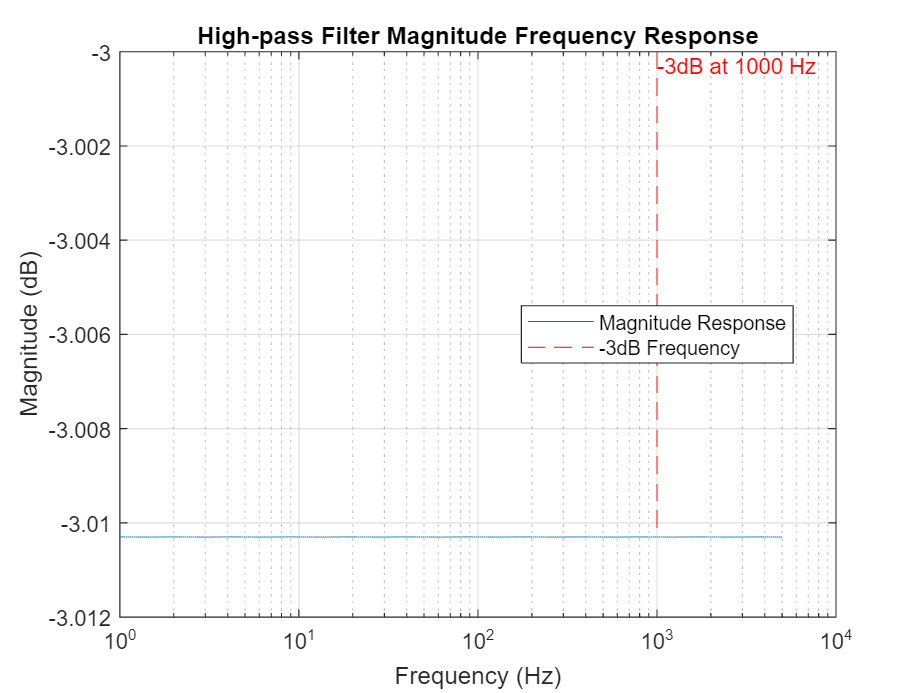

%part g: plot the magnitude frequency response from 0 to 5kHz
% Frequency range from 0 to 5 kHz
frequency_range = logspace(0, log10(5000), 1000); % Logarithmic frequency scale

% Calculate the magnitude frequency response
magnitude_response = abs((d1 * 1i * frequency_range) ./ (c1 * 1i * frequency_range + c0));

% Plot the magnitude frequency response
figure;
semilogx(frequency_range, 20 * log10(magnitude_response)); % Convert magnitude to dB
title('High-pass Filter Magnitude Frequency Response');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

% Show -3dB frequency on the plot
hold on;
line([f_minus_3dB, f_minus_3dB], [-3, max(20 * log10(magnitude_response))], 'Color', 'red', 'LineStyle', '--');
text(f_minus_3dB, -3, sprintf('-3dB at %d Hz', f_minus_3dB), 'Color', 'red', 'VerticalAlignment', 'top');

% Show the plot legend
legend('Magnitude Response', '-3dB Frequency', 'Location', 'best');

%part h: use the impulse invariant method to obtain transfer function H(z)
% Continuous-time transfer function
numerator = [0, d1];

denominator = [c1, c0];
Hs = tf(numerator, denominator);

% Sampling time (you can adjust this based on your requirements)
Ts = 1/10000; % 10 kHz sampling frequency, for example

% Discretize the transfer function using the impulse invariant method
Hz = c2d(Hs, Ts, 'impulse');

% Display the discrete-time transfer function
disp('Discrete-time transfer function H(z):');

Discrete-time transfer function H(z):


disp(Hz); %this isn't displaying Hz in the format I was expecting...

  tf with properties:

       Numerator: {[7.0711e-05 -2.2204e-20]}
     Denominator: {[1 -1]}
        Variable: 'z'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 1.0000e-04
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



%pat i: use the bilinear transformation to design Hz and Hs such that the
%cuttoff is wc = pi/2.
% Cutoff frequency for discrete-time transfer function (wc = pi/2)
wc_discrete = pi/2;

% Sampling period (you can adjust this based on your requirements)
T = 0.1; % Example: Sampling period of 0.1 seconds

% Bilinear transformation
numerator_d = polyval(d1, exp(1i * wc_discrete * T/2));
denominator_d = polyval([c1, c0], exp(1i * wc_discrete * T/2));

% Display the coefficients of the discrete-time transfer function
disp('Discrete-time transfer function coefficients:');

Discrete-time transfer function coefficients:


disp(['Numerator Coefficients: ' num2str(numerator_d)]);

Numerator Coefficients: 0.70711


disp(['Denominator Coefficients: ' num2str(denominator_d)]);

Denominator Coefficients: 0.99692+0.078459i



% Construct the discrete-time transfer function
Hz = tf(numerator_d, denominator_d, T);


% Display the discrete-time transfer function
disp('Discrete-time transfer function H(z):');

Discrete-time transfer function H(z):


disp(Hz);

  tf with properties:

       Numerator: {[0.7071]}
     Denominator: {[0.9969 + 0.0785i]}
        Variable: 'z'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0.1000
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



## Problem 2 

%part a: design a low pass digital filter from the butterworkth analog
%filter with the following specifications: Rp = 2dB, As = 20dB, Fs =
%1000Hz, Fp = 20Hz, and Fs = 60Hz. Use the impulse method to find the
%digital filter.

% Specifications
Rp = 2;       % Passband ripple in dB
As = 20;      % Stopband attenuation in dB
Fs = 1000;    % Sampling frequency in Hz
Fp = 20;      % Passband edge frequency in Hz
Fst = 60;     % Stopband edge frequency in Hz

% Convert frequencies to normalized values
wp = 2 * pi * Fp / Fs;
ws = 2 * pi * Fst / Fs;

% Calculate the order of the analog Butterworth filter
n = log10((10^(0.1*As) - 1) / (10^(0.1*Rp) - 1)) / (2 * log10(ws/wp));

% Round up to the nearest integer
n = ceil(n);

% Calculate the cutoff frequency for the analog Butterworth filter
wc = wp / ((10^(0.1*Rp) - 1)^(1/(2*n)));

% Design the analog Butterworth filter
[num, den] = butter(n, wc, 's');

% Convert the analog filter to a digital filter using the impulse invariant method
[num_digital2a, den_digital2a] = impinvar(num, den, Fs);

% Display the results
disp('Analog Butterworth Filter Coefficients:')

Analog Butterworth Filter Coefficients:


disp('Numerator Coefficients (analog):');

Numerator Coefficients (analog):


disp(num);

         0         0         0    0.0026



disp('Denominator Coefficients (analog):');

Denominator Coefficients (analog):


disp(den);

    1.0000    0.2748    0.0378    0.0026




disp('Digital Filter Coefficients:')

Digital Filter Coefficients:


disp('Numerator Coefficients (digital):');

Numerator Coefficients (digital):


disp(num_digital2a);

   1.0e-11 *

   -0.0000    0.1297    0.1297         0



disp('Denominator Coefficients (digital):');

Denominator Coefficients (digital):


disp(den_digital2a);

    1.0000   -2.9997    2.9995   -0.9997



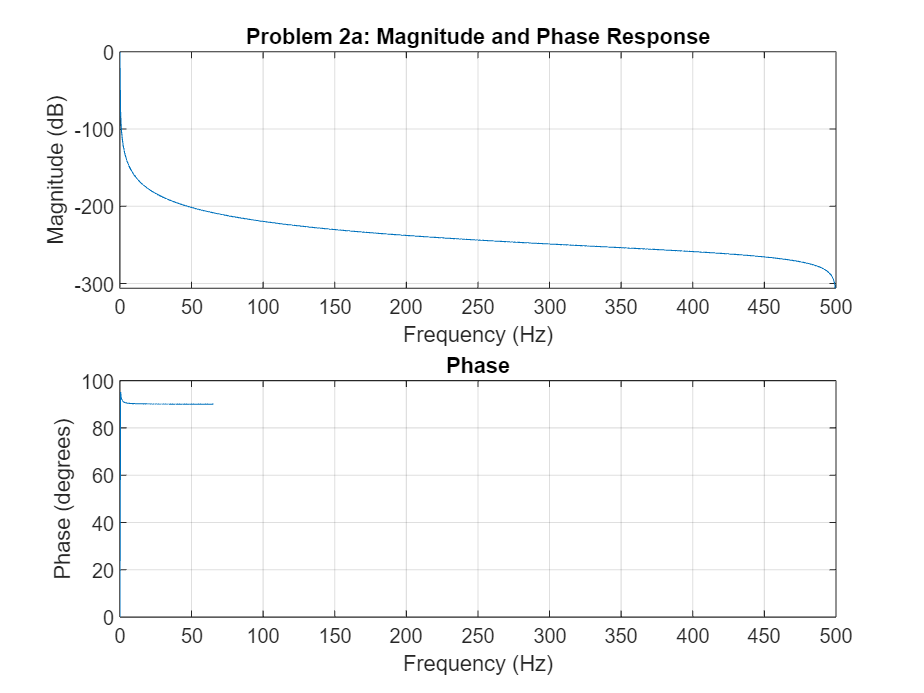


% Plot the frequency response of the digital filter
freqz(num_digital2a, den_digital2a, 1024, Fs);
title('Problem 2a: Magnitude and Phase Response');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;


%as can be seen by the phase response plot, the phase is linear over our
%frequency range of interest.



%Problem 2 part b: repeat the problem in [a] but now use bilinear
%transformation method to design the digital filter.
% Specifications
Rp = 2;       % Passband ripple in dB
As = 20;      % Stopband attenuation in dB
Fs = 1000;    % Sampling frequency in Hz
Fp = 20;      % Passband edge frequency in Hz
Fst = 60;     % Stopband edge frequency in Hz

% Convert frequencies to normalized values
wp = 2 * pi * Fp / Fs;
ws = 2 * pi * Fst / Fs;

% Calculate the order of the analog Butterworth filter
n = log10((10^(0.1*As) - 1) / (10^(0.1*Rp) - 1)) / (2 * log10(ws/wp));

% Round up to the nearest integer
n = ceil(n);

% Calculate the cutoff frequency for the analog Butterworth filter
wc = wp / ((10^(0.1*Rp) - 1)^(1/(2*n)));

% Design the analog Butterworth filter
[num, den] = butter(n, wc, 's');

% Convert the analog filter to a digital filter using the bilinear transformation
[num_digital2b, den_digital2b] = bilinear(num, den, Fs);

% Display the results
disp('Analog Butterworth Filter Coefficients:')

Analog Butterworth Filter Coefficients:


disp('Numerator Coefficients (analog):');

Numerator Coefficients (analog):


disp(num);

         0         0         0    0.0026



disp('Denominator Coefficients (analog):');

Denominator Coefficients (analog):


disp(den);

    1.0000    0.2748    0.0378    0.0026




disp('Digital Filter Coefficients:')

Digital Filter Coefficients:


disp('Numerator Coefficients (digital):');

Numerator Coefficients (digital):


disp(num_digital2b);

   1.0e-12 *

    0.3243    0.9730    0.9712    0.3249



disp('Denominator Coefficients (digital):');

Denominator Coefficients (digital):


disp(den_digital2b);

    1.0000   -2.9997    2.9995   -0.9997



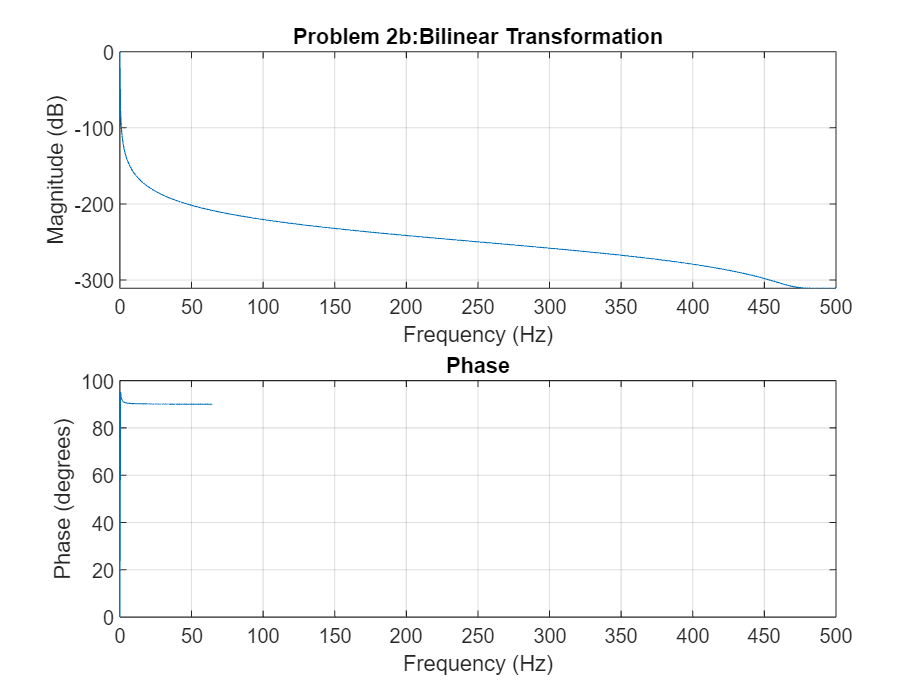


% Plot the frequency response of the digital filter
freqz(num_digital2b, den_digital2b, 1024, Fs);
title('Problem 2b:Bilinear Transformation');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

## Problem 3 

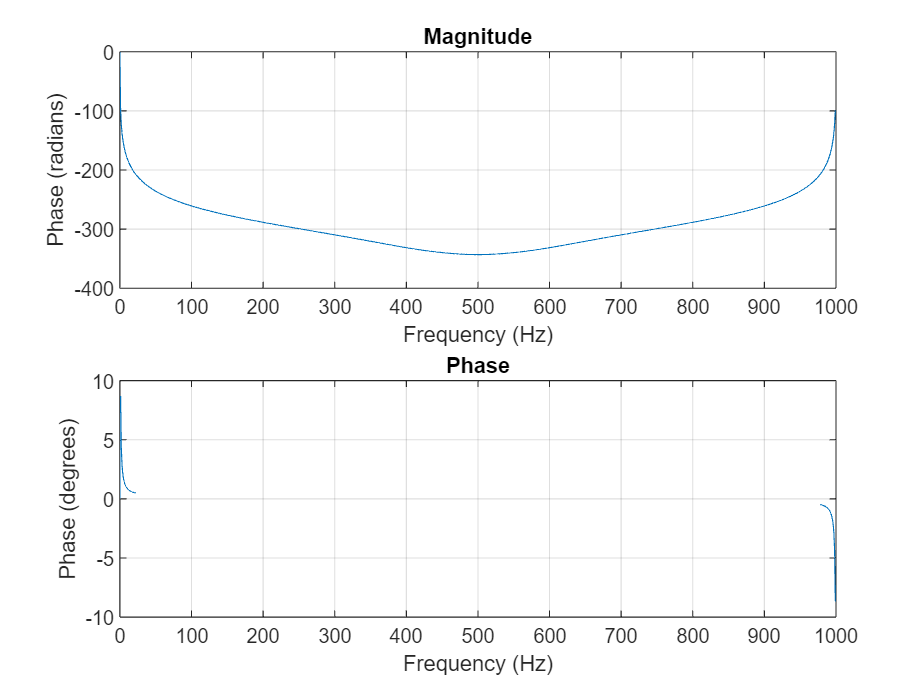

%problem 3 part a
% Specifications
Rp = 2;        % Passband ripple in dB
As = 20;       % Stopband attenuation in dB
Fs = 1000;     % Sampling frequency in Hz
Fp1 = 40;      % Lower passband edge frequency in Hz
Fp2 = 80;      % Upper passband edge frequency in Hz

% Convert frequencies to normalized values
wp1 = 2 * pi * Fp1 / Fs;
wp2 = 2 * pi * Fp2 / Fs;

% Calculate the order of the analog Butterworth filter
n = log10((10^(0.1*As) - 1) / (10^(0.1*Rp) - 1)) / (2 * log10(wp2/wp1));

% Round up to the nearest integer
n = ceil(n);

% Calculate the cutoff frequency for the analog Butterworth filter
wc = sqrt(wp1 * wp2);

% Design the analog Butterworth filter
[num, den] = butter(n, wc, 's');

% Convert the analog filter to a digital bandstop filter using the bilinear transformation
[num_digital3, den_digital3] = bilinear(num, den, Fs);

% Plot the magnitude and phase responses of the digital filter
figure;

% Magnitude response
subplot(2, 1, 1);
freqz(num_digital3, den_digital3, 1024, Fs);
title('Problem3a: Bandstop Digital Filter Response');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

% Phase response
subplot(2, 1, 2);
freqz(num_digital3, den_digital3, 1024, Fs, 'whole');
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');
grid on;


%is the phase linear over the frequency range of interest?


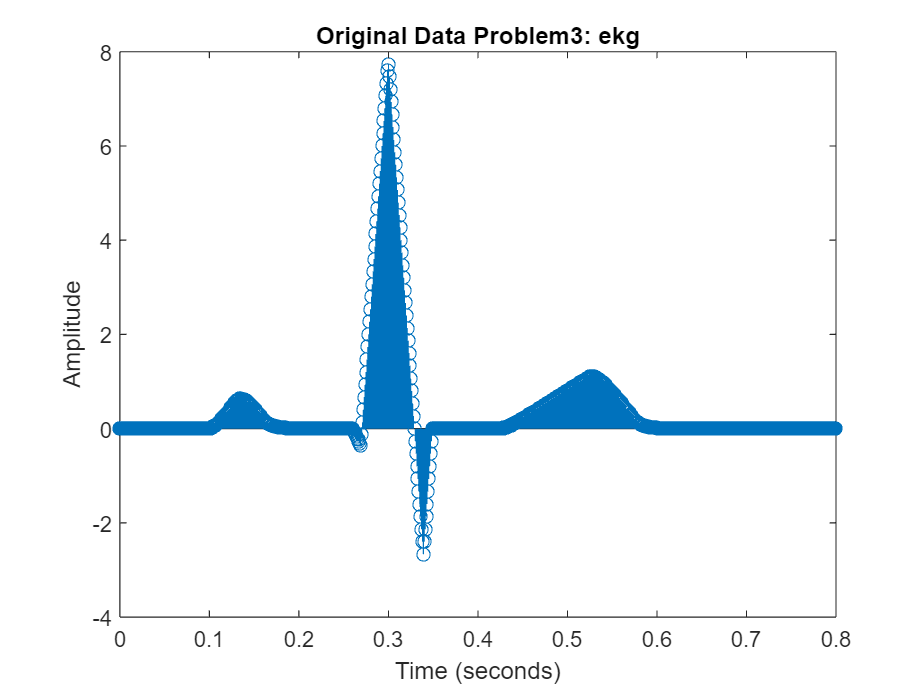

%problem 3 part b: filter the signal ekg60n data using the filters designed
%in the problem and problems 2a and 2b.

load ('ekg.mat'); %provides ekg and ekg60n

% Plot the original and filtered data
t = (0:length(ekg60n)-1) / Fs; % Time vector

%displaying original data
figure; stem(t, ekg);
title('Original Data Problem3: ekg');
xlabel('Time (seconds)');
ylabel('Amplitude');

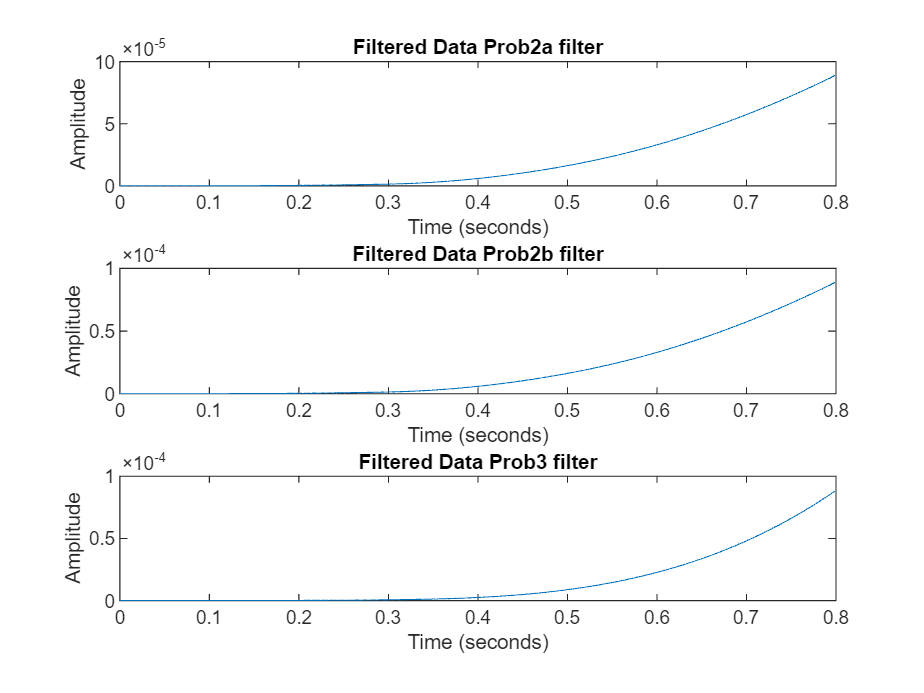


%now to pull from problem 2a
filtered_data2a = filter(num_digital2a, den_digital2a, ekg60n);
figure; 
subplot(3,1,1);
plot(t, filtered_data2a);
title('Filtered Data Prob2a filter');
xlabel('Time (seconds)');
ylabel('Amplitude');

%problem 2b pull 
filtered_data2b = filter(num_digital2b, den_digital2b, ekg60n);
subplot(3,1,2);
plot(t, filtered_data2b);
title('Filtered Data Prob2b filter');
xlabel('Time (seconds)');
ylabel('Amplitude');

%finally problem 3 filter
filtered_data3 = filter(num_digital3, den_digital3, ekg60n);
subplot(3,1,3);
plot(t, filtered_data3);
title('Filtered Data Prob3 filter');
xlabel('Time (seconds)');
ylabel('Amplitude');

%as you can see by the three different filtered versions of the data, the
%frist filter from problem 2a has the best resolution and displays the full
%amplitude required to get a better idea of the signal results.



## Problem 4 

%we are given a transfer function H(s) = 100pi/(s + 100pi). wewant to
%replace the analog filter with a digital equivalent noting that the
%frequencies to the signal are less than 50Hz, with almost equal
%representation at all frequencies.

%we also are gien that there is strong interference signal at 95 Hz with
%roughly the same amplitude as those in the input signal...

%we are given the following input signal:
% xt = 5 + 5cos(40pit) + 50cos(80pit) + 5cos(190pit)
%where 0, 20, 40 Hz freuqnecy signals are the desired values and 95 hz is
%the one we wish to remove....

%part a
% Given analog filter transfer function
numerator = 100 * pi;
denominator = [1, 100 * pi];

% Given sampling frequency
fs = 200; % Hz

% Step 2: Impulse Invariant Design
[num_digital, den_digital] = impinvar(numerator, denominator, fs);

% Step 3: Normalization
[num_digital] = norm(num_digital);
[den_digital] = norm( den_digital);

% Step 4: Display filter coefficients
disp('Digital Filter Coefficients:');

Digital Filter Coefficients:


disp('Numerator Coefficients (b):');

Numerator Coefficients (b):


disp(num2str(num_digital));

1.5708


disp('Denominator Coefficients (a):');

Denominator Coefficients (a):


disp(num2str(den_digital));

1.0214


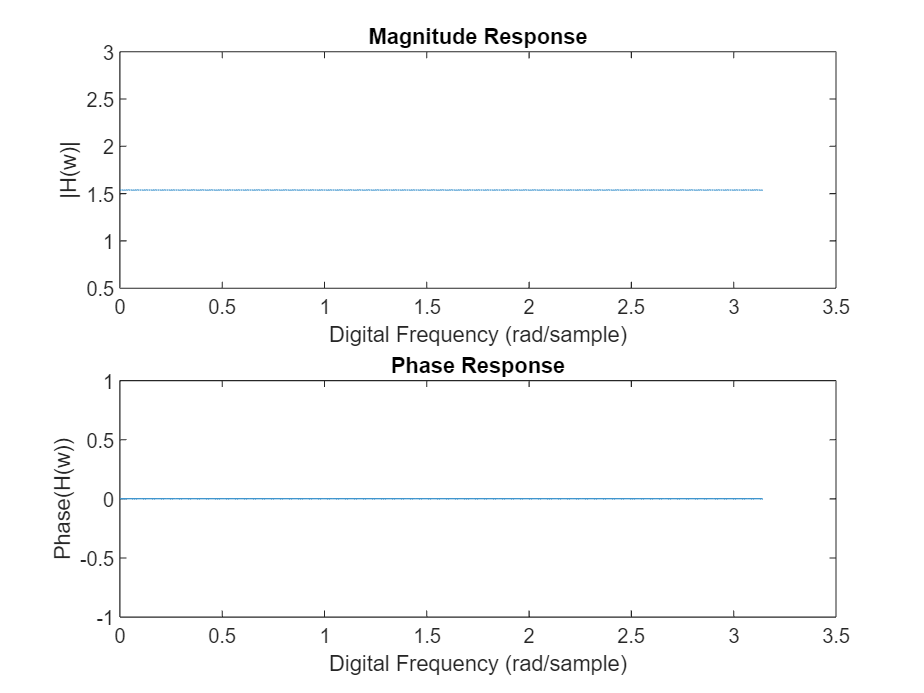


% Step 5: Magnitude and Phase Plot
w = linspace(0, pi, 1000); % Digital frequency vector
Hw = freqz(num_digital, den_digital, w, fs);

figure;
subplot(2, 1, 1);
plot(w, abs(Hw));
title('Magnitude Response');
xlabel('Digital Frequency (rad/sample)');
ylabel('|H(w)|');

subplot(2, 1, 2);
plot(w, angle(Hw));
title('Phase Response');
xlabel('Digital Frequency (rad/sample)');
ylabel('Phase(H(w))');

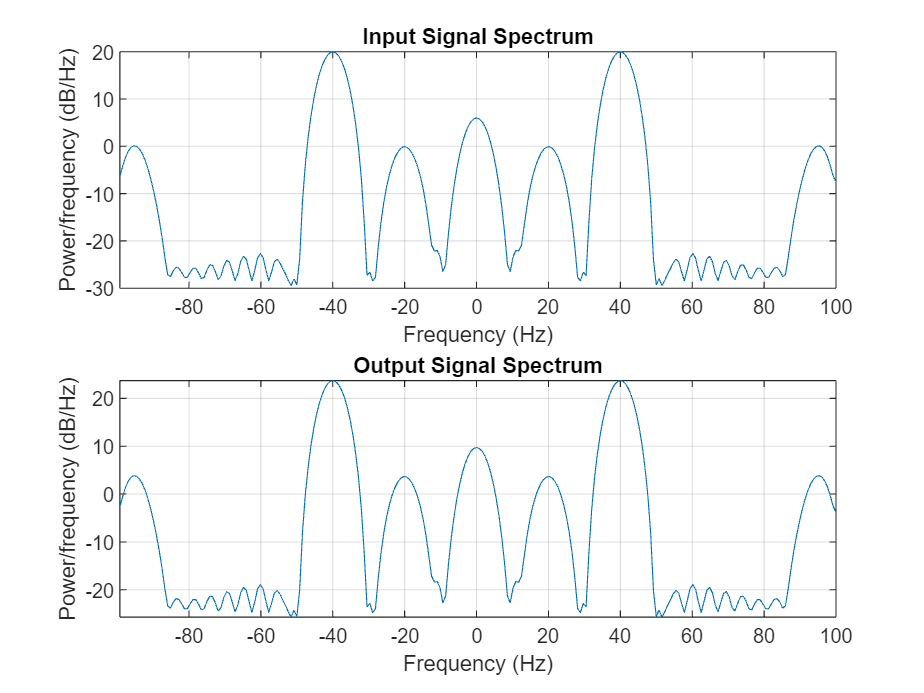


% Step 6: Sample the input signal
t = 0:1/fs:1; % Time vector
xt = 5 + 5*cos(40*pi*t) + 50*cos(80*pi*t) + 5*cos(190*pi*t);

% Step 7: Filter the input signal
yt = filter(num_digital, den_digital, xt);

% Step 8: Analyze the spectrum of the output signal
figure;
subplot(2, 1, 1);
pwelch(xt, [], [], [], fs, 'centered');
title('Input Signal Spectrum');

subplot(2, 1, 2);
pwelch(yt, [], [], [], fs, 'centered');
title('Output Signal Spectrum');


%how effective was this at removing the interference?
%I struggled at being able to display more than a straight line so I don't
%know how much initial interference there was aside from comparing the
%input and output but, thre doesnn't appear to be much change here aside
%from an increase in amplitude.

%Problem 4 part b: repeat part a assuming the equivalent digital system to
%be operated at fs = 1000hz;

% Updated Sampling Frequency
fs = 1000; % Hz

% Updated Impulse Invariant Design
[num_digital, den_digital] = impinvar(numerator, denominator, fs);

% Updated Time Vector
t = 0:1/fs:1; % Time vector

% Given analog filter transfer function
numerator = 100 * pi;
denominator = [1, 100 * pi];

% Updated Sampling Frequency
fs = 1000; % Hz

% Updated Impulse Invariant Design
[num_digital, den_digital] = impinvar(numerator, denominator, fs);

% Normalization
[num_digital] = norm(num_digital);
[den_digital] = norm(den_digital);

% Display filter coefficients
disp('Digital Filter Coefficients:');

Digital Filter Coefficients:


disp('Numerator Coefficients (b):');

Numerator Coefficients (b):


disp(num2str(num_digital));

0.31416


disp('Denominator Coefficients (a):');

Denominator Coefficients (a):


disp(num2str(den_digital));

1.2383


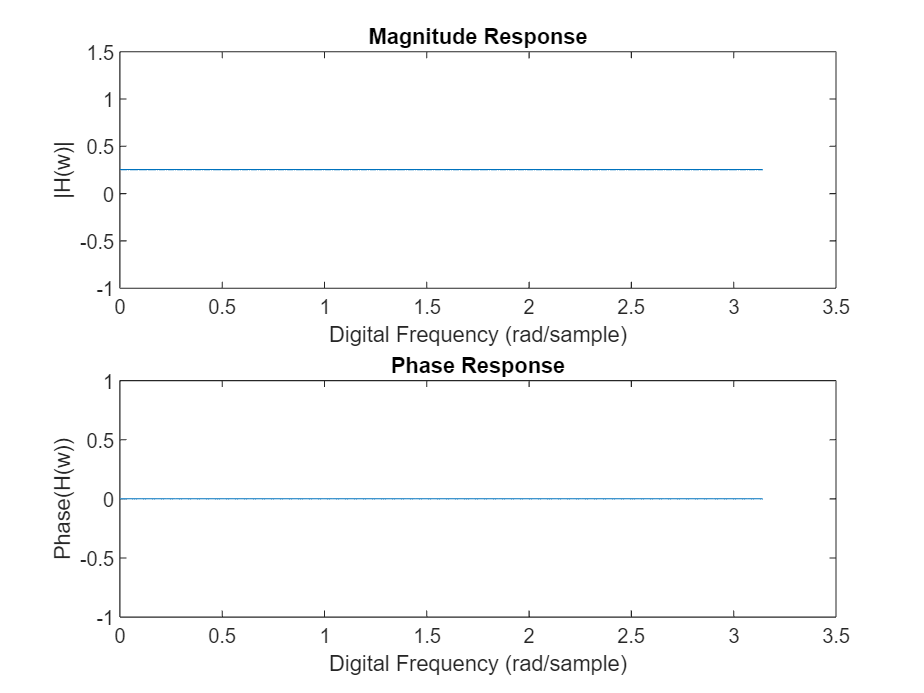


% Magnitude and Phase Plot
w = linspace(0, pi, 1000); % Digital frequency vector
Hw = freqz(num_digital, den_digital, w, fs);

figure;
subplot(2, 1, 1);
plot(w, abs(Hw));
title('Magnitude Response');
xlabel('Digital Frequency (rad/sample)');
ylabel('|H(w)|');

subplot(2, 1, 2);
plot(w, angle(Hw));
title('Phase Response');
xlabel('Digital Frequency (rad/sample)');
ylabel('Phase(H(w))');

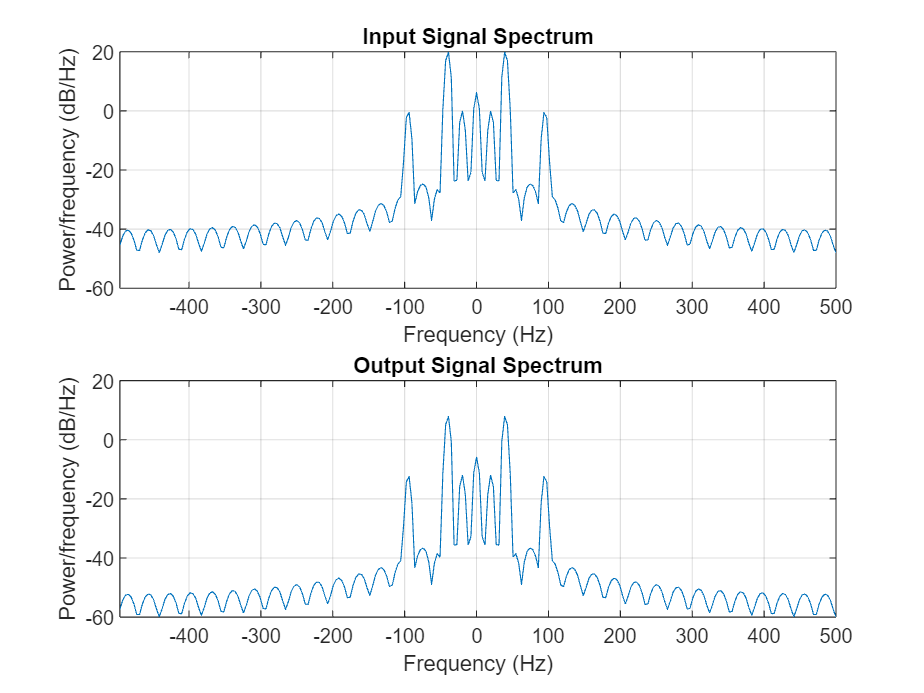


% Sample the input signal
t = 0:1/fs:1; % Updated Time Vector
xt = 5 + 5*cos(40*pi*t) + 50*cos(80*pi*t) + 5*cos(190*pi*t);

% Filter the input signal
yt = filter(num_digital, den_digital, xt);

% Analyze the spectrum of the output signal
figure;
subplot(2, 1, 1);
pwelch(xt, [], [], [], fs, 'centered');
title('Input Signal Spectrum');

subplot(2, 1, 2);
pwelch(yt, [], [], [], fs, 'centered');
title('Output Signal Spectrum');



%part c: Which of the two filters above has more uniform response over the
%passband and greater attenuation at the frequency of the interferring
%signal?

%based on part a and part b, the filter that has the most uniform response
%over the passband and greater attenuation at the frequency of the
%interfeering signal is the second filter with fs = 1000hz.

## Problem 5

%design a minimum order IIR digital filter to satisfy the specifications.
% Given specifications
passband_edges = [0.35*pi, 0.5*pi];
stopband_edges = [0, 0.3*pi, 0.6*pi, pi];
passband_ripple = 1; % dB
stopband_attenuation = 40; % dB

% Normalize passband and stopband frequencies
passband_freqs = [passband_edges(1)/(0.5*pi), passband_edges(2)/(0.5*pi)];
stopband_freqs = [stopband_edges(1)/(0.5*pi), stopband_edges(2)/(0.5*pi), stopband_edges(3)/(0.5*pi), stopband_edges(4)/(0.5*pi)];

% Design low-pass Butterworth filter
filter_order = 2; % You can adjust this based on your requirements
[lowpass_b, lowpass_a] = butter(filter_order, passband_freqs(1), 'low');

% Apply frequency transformations to obtain a bandpass response
center_freq = mean(passband_freqs);
bw = diff(passband_freqs);
[numerator, denominator] = lp2bp(lowpass_b, lowpass_a, center_freq, bw);

% Display the filter coefficients
disp('Filter Coefficients:');

Filter Coefficients:


disp('Numerator (b):');

Numerator (b):


disp(num2str(numerator));

0.505       0.303     0.77518     0.21892     0.26361


disp('Denominator (a):');

Denominator (a):


disp(num2str(denominator));

1     0.22434      1.4695     0.16208     0.52201




% Plot the magnitude response of the Butterworth filter
fvtool(numerator, denominator, 'Analysis', 'freq', 'MagnitudeDisplay', 'Magnitude');


%part a: the filter order: 2
%part b: find the passband and stopband edges

% Calculate and display the band-edge frequencies
passband_edge_freqs = [passband_edges(1)/(2*pi), passband_edges(2)/(2*pi)];
stopband_edge_freqs = [stopband_edges(1)/(2*pi), stopband_edges(2)/(2*pi), stopband_edges(3)/(2*pi), stopband_edges(4)/(2*pi)];

disp(['Passband Edge Frequencies: ' num2str(passband_edge_freqs)]);

Passband Edge Frequencies: 0.175        0.25


disp(['Stopband Edge Frequencies: ' num2str(stopband_edge_freqs)]);

Stopband Edge Frequencies: 0        0.15         0.3         0.5
